# 2D Kalman Filter on OpenPose Data

**Initialization**

clear all;
close all ;
clc;
base_dir="data\";
cd(base_dir);

Error using cd
Unable to change current folder to 'C:\Users\Clarisse Alago\Documents\MATLAB\gait-analysis\pre-processing\matlab\data\data' (Name is nonexistent or not a folder).

Video File & Keypoints

vid = VideoReader('vid_out_colab.avi')

vid =   VideoReader with properties:

   General Properties:
            Name: 'vid_out_colab.avi'
            Path: 'C:\Users\Clarisse Alago\Documents\MATLAB\gait-analysis\pre-processing\matlab\data'
        Duration: 4.5000
     CurrentTime: 0
       NumFrames: 135

   Video Properties:
           Width: 960
          Height: 540
       FrameRate: 30
    BitsPerPixel: 3
     VideoFormat: 'RGB24'


%raw_vid = VideoReader('vid_out.avi')
all_keypoints= readtable('keypoints_colab_fixed2.csv')

all_keypoints = 135×44 table
    frame    elapsed_time_s_    neck_x     neck_y     neck_c     spine_hip_x    spine_hip_y    spine_hip_c    r_hip_x    r_hip_y    r_hip_c    r_knee_x    r_knee_y    r_knee_c    r_ankle_x    r_ankle_y    r_ankle_c    r_heel_x    r_heel_y    r_heel_c    r_bigtoe_x    r_bigtoe_y    r_bigtoe_c    r_smalltoe_x    r_smalltoe_y    r_smalltoe_c    l_hip_x    l_hip_y    l_hip_c    l_knee_x    l_knee_y    l_knee_c    l_ankl


% specifying keypoint of interest
keypoint=[all_keypoints.l_smalltoe_x all_keypoints.l_smalltoe_y];

%We will de-normalize openpose measurements
keypoint=[keypoint(:,1)*vid.Width keypoint(:,2)*vid.Height];


Defining Variables

dt = 0.04; % sampling rate
frame_start = 10; % starting frame
u = 10; % !!! input/acceleration magnitude  !!!Important
Z=[keypoint(frame_start,1);keypoint(frame_start,2);-100;5]; %initialized state [pos_x, pos_y, v_x,v_y]
X_estimate= Z; % estimate of the initial location
process_noise= 10; % !!! if high we expect a lot of jumping around the variability in how fast the object is speeding up (stdv of acceleration: meters/sec^2) !!!
noise_x = 0.01; % !! measurement confidentiality measurement noise in x axis
noise_y = 0.005; % measurement noise in y axis

Defining Matrices

% Measurement Noise Covariance Matrix
R = [noise_x 0; 0 noise_y]; 

% Process noise matrix
Q = [dt^4/4 0 dt^3/2 0; ...
    0 dt^4/4 0 dt^3/2; ...
    dt^3/2 0 dt^2 0; ...
    0 dt^3/2 0 dt^2].*process_noise^2;

% Initial estimate for Variance
P = Q;

% State transition matrix
F = [1 0 dt 0; 0 1 0 dt; 0 0 1 0; 0 0 0 1];

% Control Matrix
G = [(dt^2/2); (dt^2/2); dt; dt];

% Observation Matrix
H = [1 0 0 0; 0 1 0 0 ];

Initializing result variables

%actual variables ?
OP= [];

Initilizing estimation variables

pos_all_estimate=[];
v_all_estimate =[];
P_estimate = P;
predict_state = [];
predict_var =[];

%circle stuff / may not be needed
r = 5; % r is the radius of the plotting circle
j=0:.01:2*pi; %to make the plotting circle

**Kalman Filtering**

looping through the frames

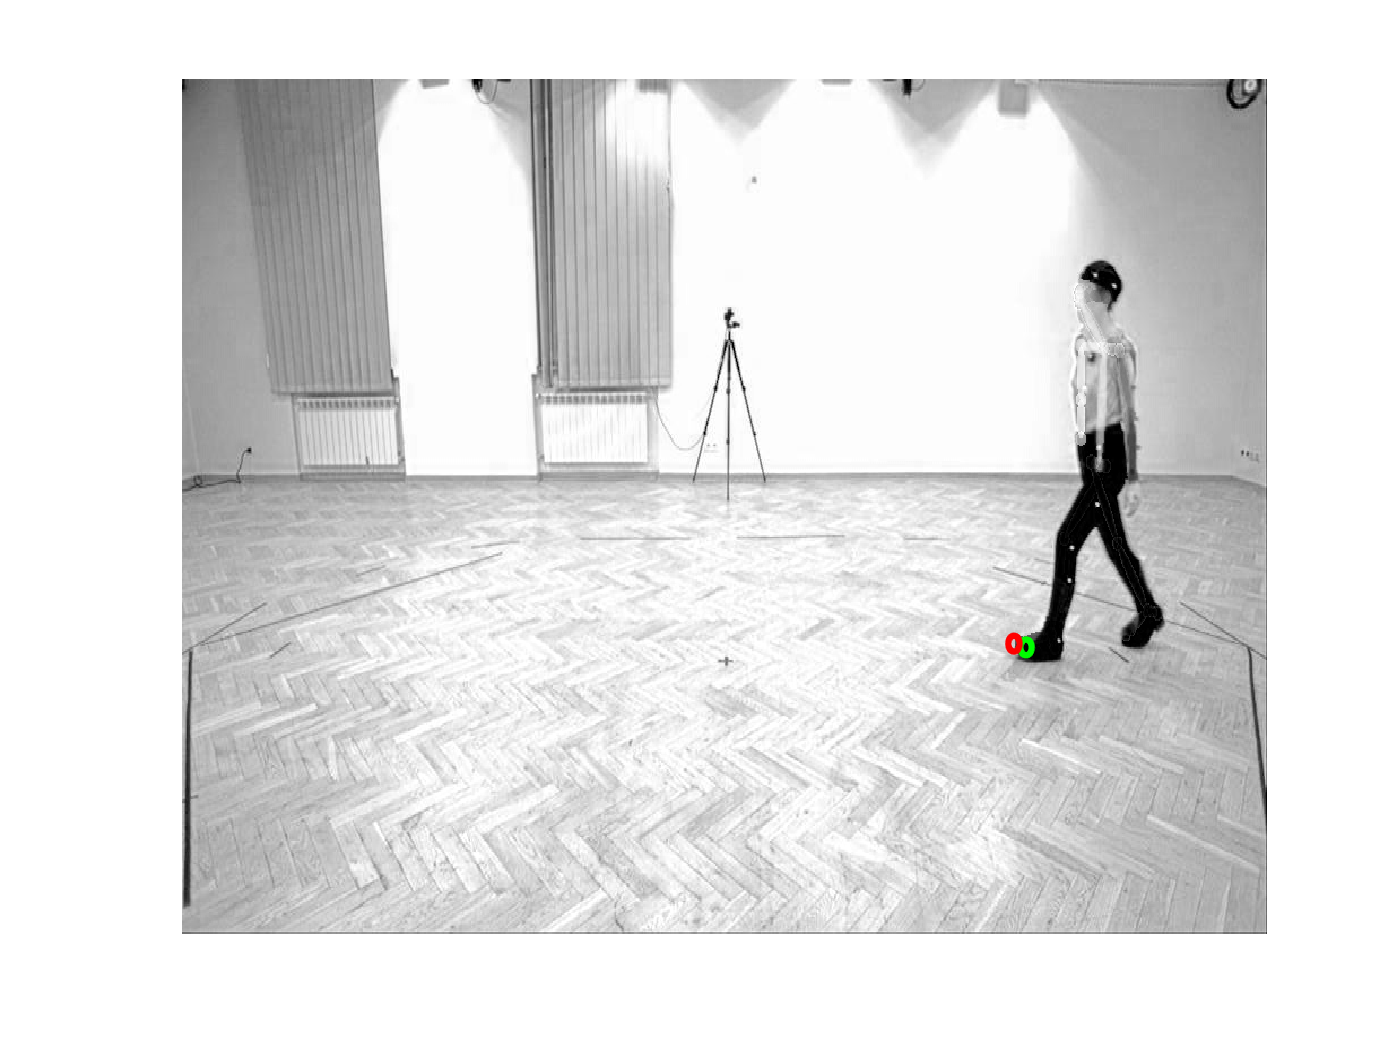

for n =frame_start:vid.numFrames
    
    % loading frame
    videoFrame = read(vid,n);
    img = videoFrame(:,:,1);
    
    % OpenPose Measurement
    OP(:,n)= [keypoint(n,1); keypoint(n,2)];
    
    
    %% KALMAN PREDICT %%
    %state
    X_estimate = F * X_estimate + G * u;
    predict_state = [predict_state;X_estimate(1)]; % ?
    
    %covariance
    P = F * P * F' + Q;
    predict_var = [ predict_var; P]; % ?
    
    %% KALMAN UPDATE %%
    %kalman gain
    K = P * H' * inv(H * P * H' + R);
    
    %state update
    X_estimate = X_estimate + K * (OP(:,n) - H * X_estimate);
    
    %covariance update
    P = (eye(4) - K*H)*P;
    
    
    % storing data
    pos_all_estimate = [pos_all_estimate; transpose(X_estimate(1:2))];
    v_all_estimate = [v_all_estimate; transpose(X_estimate(3:4))];
    
    % plotting image
    imagesc(img);
    axis off
    colormap(gray);
    hold on;
    plot(r*sin(j)+OP(1,n),r*cos(j)+OP(2,n),'.g'); % the actual tracking
    plot(r*sin(j)+X_estimate(1),r*cos(j)+X_estimate(2),'.r'); % the kalman filtered tracking
    hold off
    pause(0.1)
   
    % just for trial at n=1
    %break
end

Plotting Results

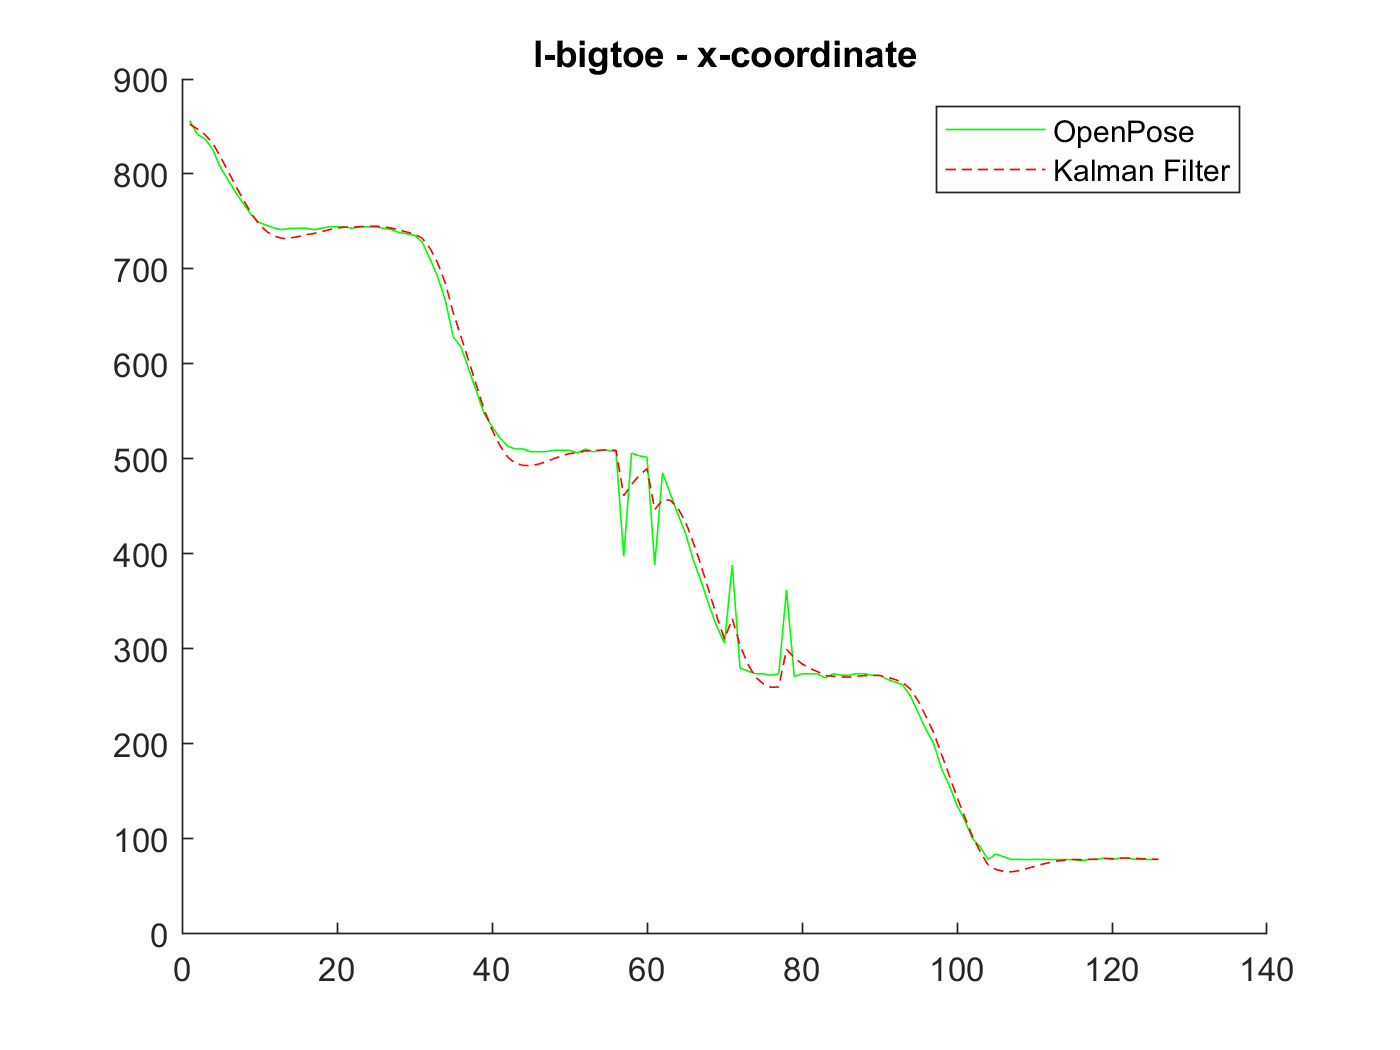

pos_all_estimate;
v_all_estimate;


% X- coordinates
figure;
hold on;
%subplot(2,1,1)
plot(keypoint(frame_start:end,1),'g-')
title("l-smalltoe - x-coordinate")
%title("OP - x")

%subplot(2,1,2)
plot(pos_all_estimate(:,1),'r--')
%title("KF - x")
legend('OpenPose', 'Kalman Filter')

hold off

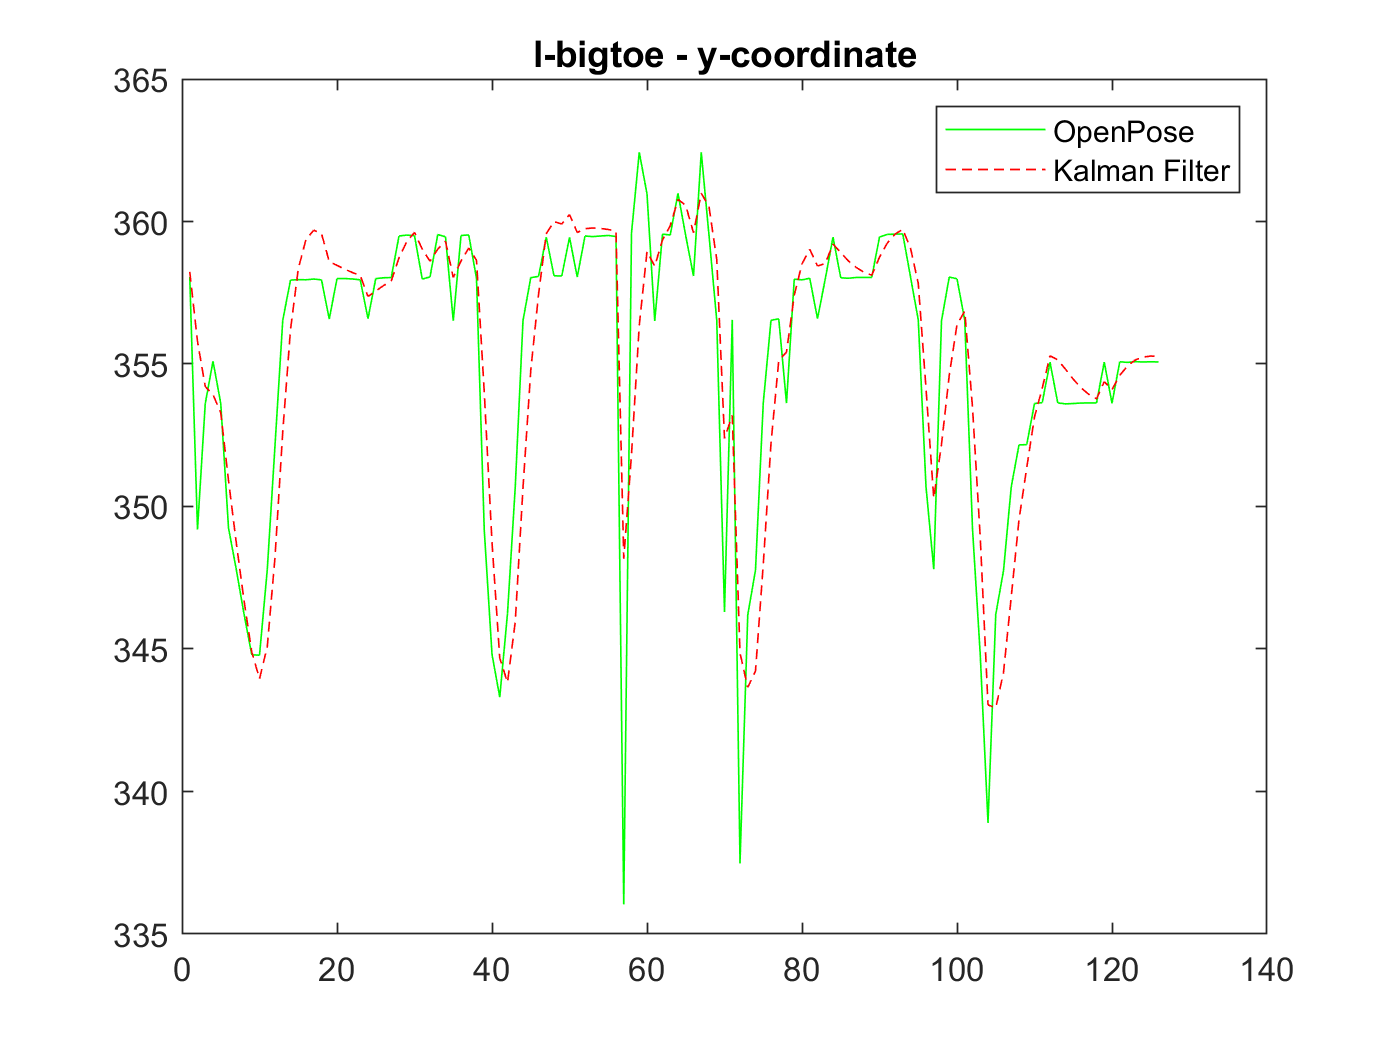

% Y- coordinates
figure;
%subplot(2,1,1)
plot(keypoint(frame_start:end,2),'g-')
hold on
title("l-smalltoe - y-coordinate")
%title("OP - y")

%subplot(2,1,2)
plot(pos_all_estimate(:,2),'r--')
legend('OpenPose', 'Kalman Filter')
%title("KF - y")
hold off


mocap= readtable('p1s1.csv');

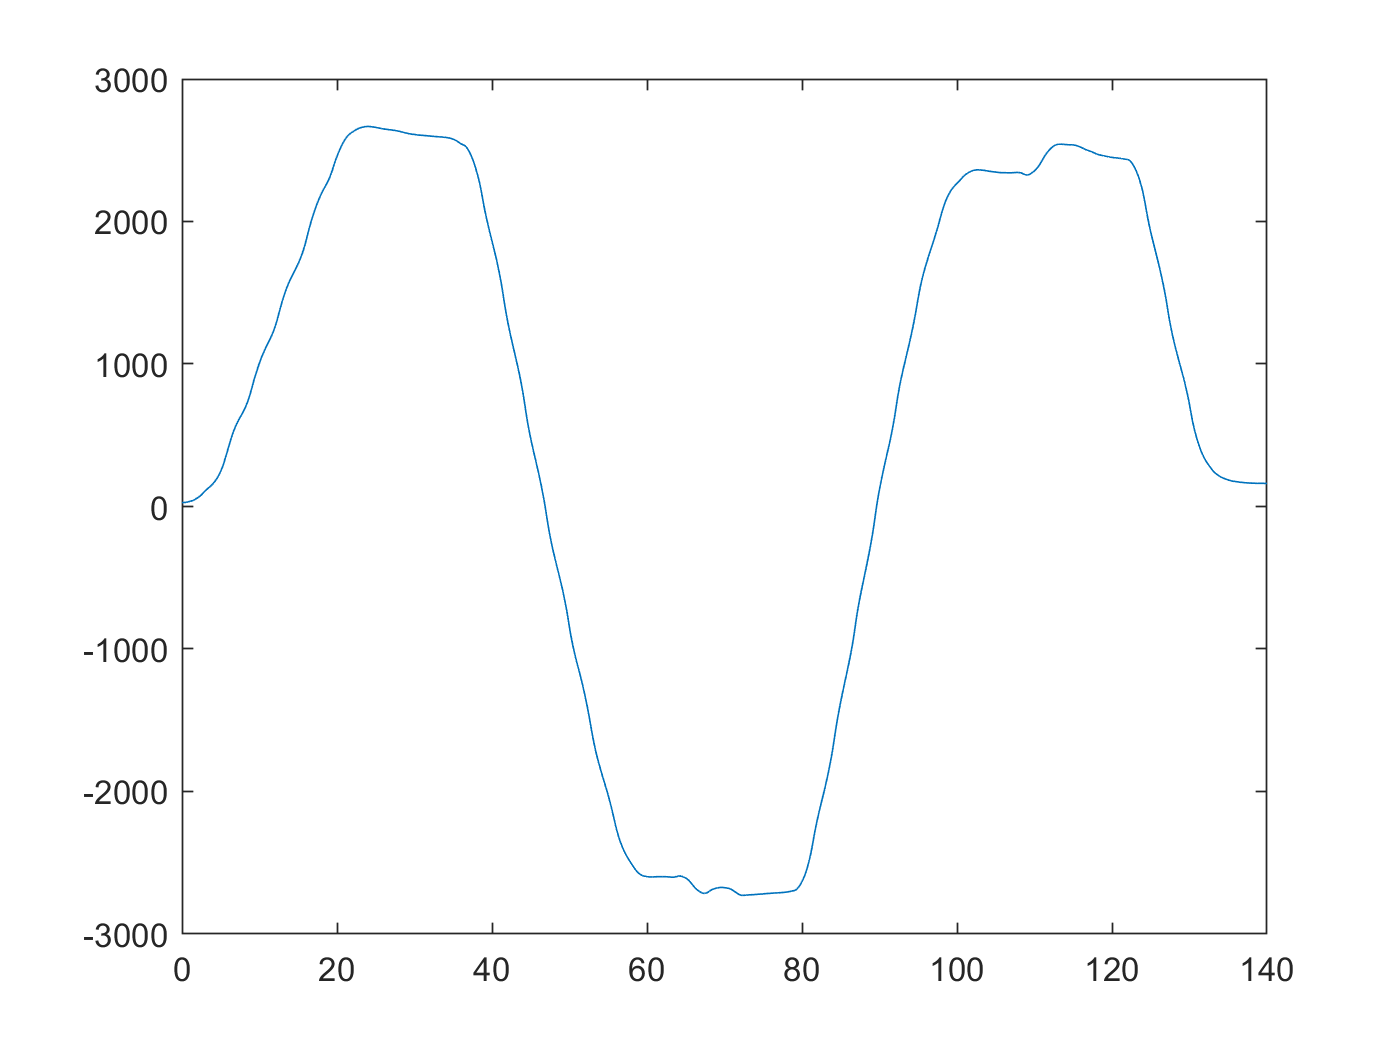


xaxis=linspace(0,140,3103);
plot(xaxis,mocap.root_tx )

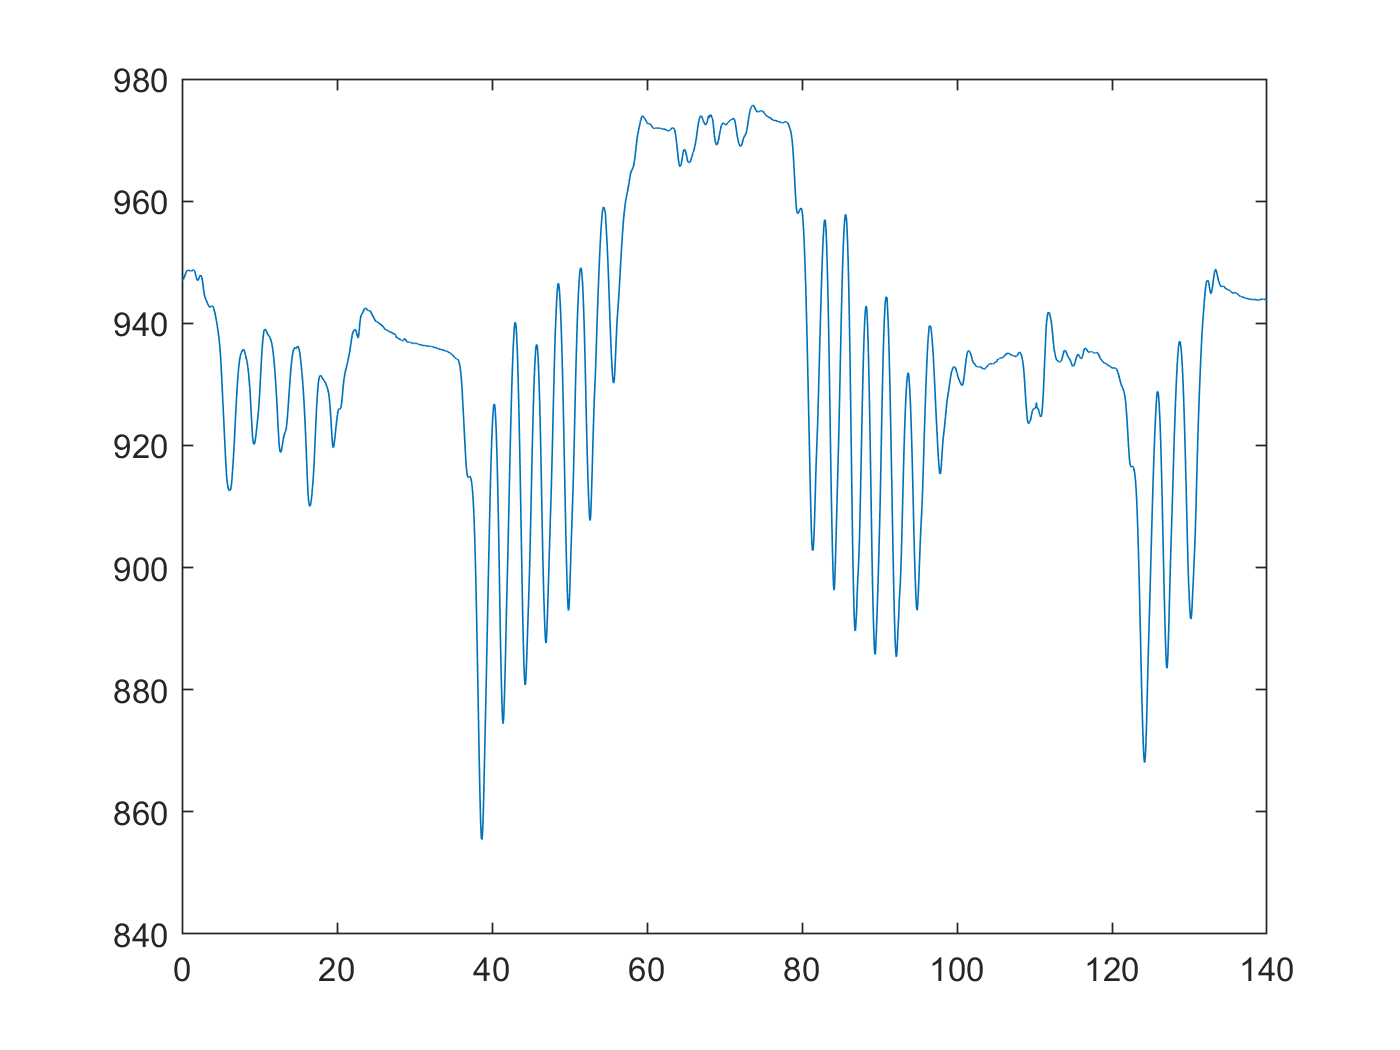

plot(xaxis,mocap.root_ty)

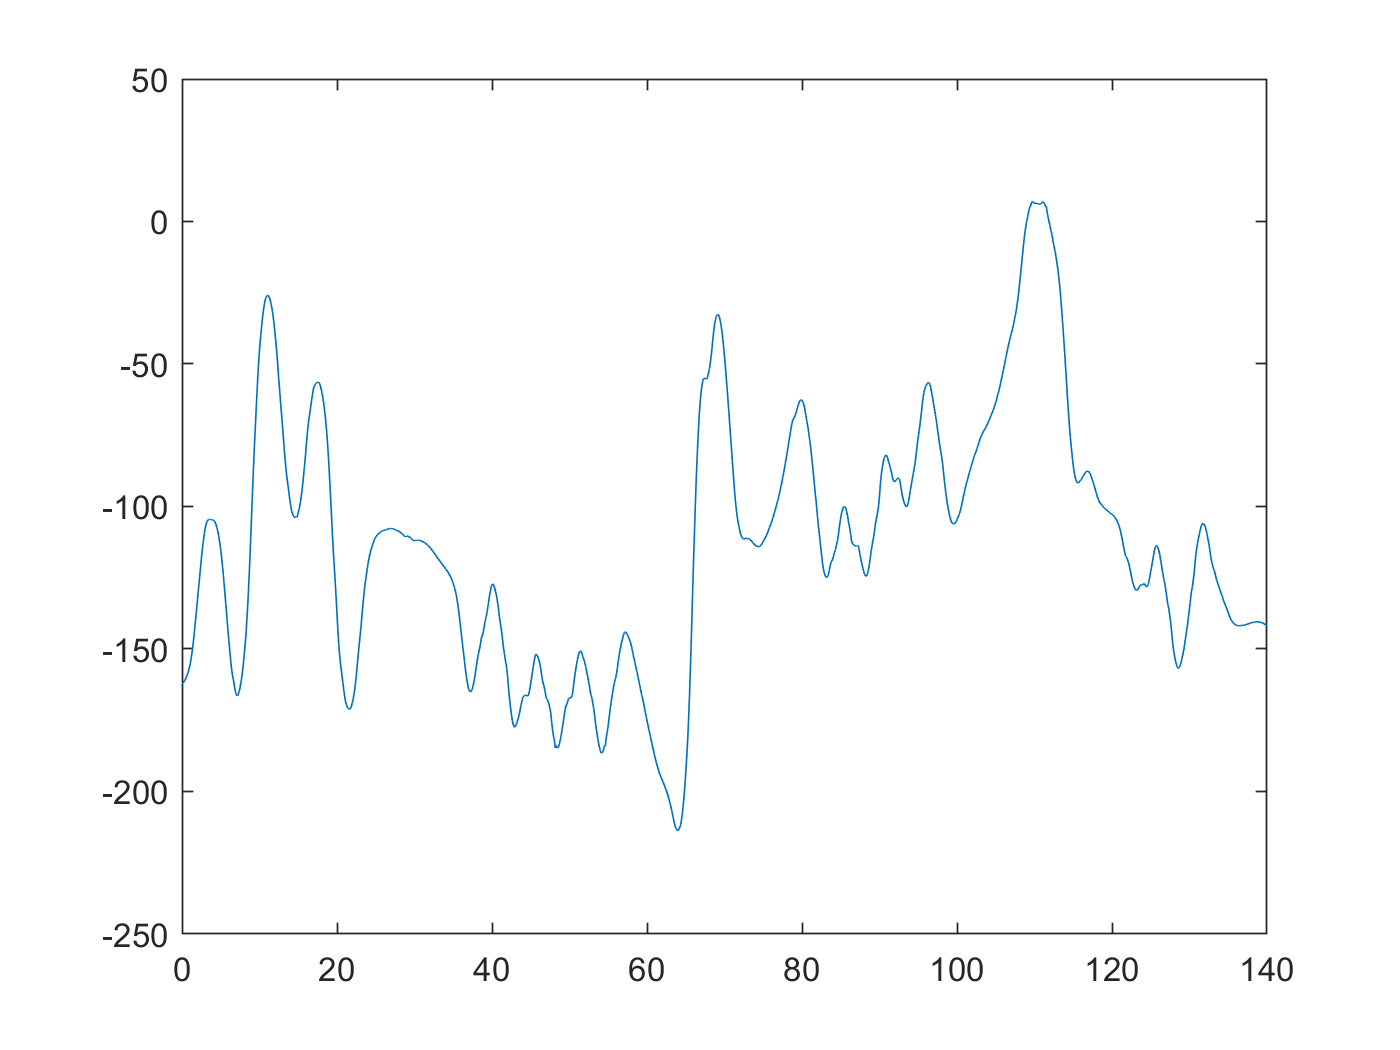

plot(xaxis,mocap.root_tz)

mocap

mocap = 3103×88 table
    x_frame    root_tx    root_ty    root_tz    root_rx    root_ry    root_rz    lowerback_rx    lowerback_ry    lowerback_rz    upperback_rx    upperback_ry    upperback_rz    thorax_rx    thorax_ry    thorax_rz    lowerneck_rx    lowerneck_ry    lowerneck_rz    upperneck_rx    upperneck_ry    upperneck_rz    head_rx    head_ry    head_rz     rshoulderjoint_rx    rshoulderjoint_ry    rshoulderjoint_rz    rhumerus_rx    rhumerus_ry    rhumerus_rz 

size(img);

% imagesc(img);
% hold on
% plot(keypoint(:,1), keypoint(:,2))
% plot(pos_all_estimate(:,1),pos_all_estimate(:,2))
% hold off

plot check

% n=70
% videoFrame = read(vid,n);
%     img = videoFrame(:,:,1);
%  %figure;
% %imagesc(img);
%     axis off
%     colormap(gray);
%     %hold on;
% % specifying keypoint of interest
% keypoint=[all_keypoints.l_smalltoe_x all_keypoints.l_smalltoe_y];
% 
% %We will de-normalize openpose measurements
% keypoint=[keypoint(:,1)*vid.Width keypoint(:,2)*vid.Height];
% 
% OP(:,n)= [keypoint(n,1); keypoint(n,2)];
% plot(r*sin(j)+OP(1,n),r*cos(j)+OP(2,n),'.g');
